# Aircraft Pitch Control System

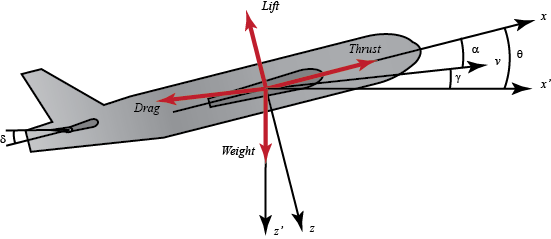

The the open-loop transfer function of the aircraft pitch dynamics (linearized) are as follows:


$$G_p \left(s\right)=\frac{\Theta \left(s\right)}{\Delta \left(s\right)}=\frac{1.151s+0.1774}{s^3 +0.739s^2 +0.921s}$$


s = tf('s');
G_p = (1.151*s+0.1774)/(s^3+0.739*s^2+0.921*s)

G_p =
 
      1.151 s + 0.1774
  -------------------------
  s^3 + 0.739 s^2 + 0.921 s
 
Continuous-time transfer function.



pole(G_p)

ans =    0.0000 + 0.0000i
  -0.3695 + 0.8857i
  -0.3695 - 0.8857i


The open-loop system is type-1 one, thus let us design a P controller one. 

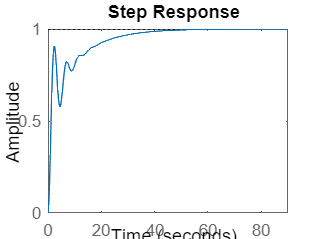

C=1;
T=feedback(C*G_p,1);
step(T)

Root-locus

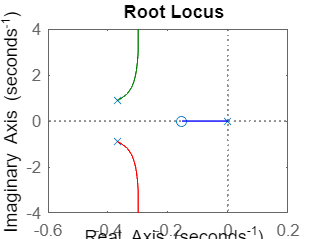

rlocus(G_p)

pole(T)

ans =   -0.3255 + 1.3816i
  -0.3255 - 1.3816i
  -0.0881 + 0.0000i


zero(T)

ans = -0.1541

All poles are dominating, zero is also in the dominant area

PD Controller, Design criteria: 0% overshoot, Settling time small as possible.

The PD controller with its resulting response

C=53.287*(1+0.25*s)

C =
 
  13.32 s + 53.29
 
Continuous-time transfer function.



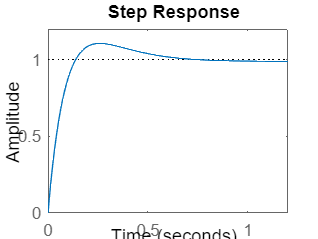

Kp=53.287; Kd=53.287*0.25;
T=feedback(C*G_p,1,-1);
step(T)